# **Fig S2G**

### **Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

 load([dataDir filesep 'A087_data_DBF4_IF.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 3×5 cell array
    {'siControl' }    {[2]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0]}
    {'siDBF4'    }    {[3]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0]}
    {'siCyclinA2'}    {[4]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0]}



framesPerHr = 60/12;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

ALL_row = [2:7];




for i = 1:length(S)
      S(i).frameDrugAdded = settings.conditions{i,5};
     S(i).frameDrugAdded = 15;
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (S(i).frameDrugAdded - S(i).POI)/framesPerHr;
end

%iRFP1 = Y15
%RFP2 = B17
% YFP3 = EdU

xthresh =5.4e6; %x value of peak
xrange = linspace(12e6,10000); %row vector of 1000 points between x and y (all the data)

for i = 1:length(conds)
    xdata = allIF(conds(i)).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(conds(i)).DNA_peak = N_peak;

end

**DBF4, APC ON**

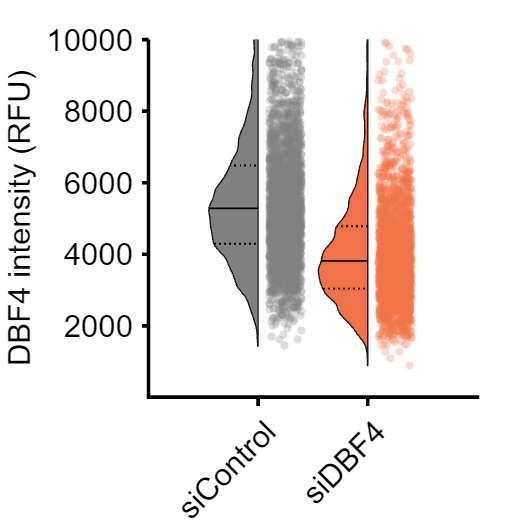

ans = 2901

ans = 2368

p = 2.4350e-167

conds=[1 2] ;

offset=0;
ally = [];
groups = [];

yval = 'iRFP1';

gateVals = {'dna','RFP1'};
rangeVals = {[0 5.5e6],[0 2^5.5]}; 
edges = linspace(12,14,30);
row_gate = [2:4];
col_gate = [2:11];

colors = [.5 .5 .5;.941 .447 .282;.4 .1 .5; 0 .7 1;.1 .4 1;];
  f1= figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
   hold on
poi_list = [1];
name = {'mitosis'};

lims = {[0 6],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
     
        ydata = [];
        plot_ydata=[];
     
     

     condition = conds(i);
    ydata = real((S(condition).(yval))); 
     rows = S(condition).wellindex(:,1);
     cols = S(condition).wellindex(:,2);
  
    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
     
    end
    
 
    ydata = ydata(totalGate & any(rows == row_gate,2)  & any(cols == col_gate,2));

    plot_ydata = ydata;

    ally = [ally;  plot_ydata];
    groups = [groups; repmat(i,size( plot_ydata))];
    length( plot_ydata)

    end

       cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);

        set(gca,'linewidth',2,'fontsize',17)

xticklabels(conditions(conds,1))
ylabel ('DBF4 intensity (RFU)')
  ylim([8 10000])
 xtickangle(45)
  set(gca,'fontsize',17)
 p=mediantest(ally(groups==1),ally(groups==2))
% print_pdf(['fig_S2g.pdf'])
end